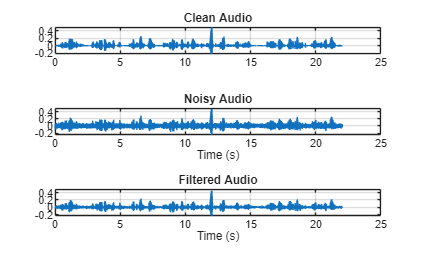

% f = randn(1000, 256);
% length(f)
% t = 0:255;
% f_continous = reshape(f.',1,[]);
% figure, plot((0:1000*256-1)/8000, f_continous); xlim([0 10]);
% w = sqrt(1-0.85185*cos((2*t+1)*pi/256)); % Hamming window, 0.85 = 0.46/0.54
% figure, plot(t, w);

% [freq, MMSE, f_windowed] = frame_processing(f);
% figure;
% plot(freq, MMSE);
% xlabel('Frequency (Hz)');
% ylabel('Amplitude (V)');
% title('MMSE over the past 1000 frames');
% grid on;
% xlim([0 8000/2]);

fs = 8000;
cleanAudio = audioread("clean\clean_test_clnsp0.wav");
% sound(cleanAudio,fs)
noise = audioread("noise\noise_test_AirConditioner_1.wav");
noiseSegment = noise(1:length(cleanAudio));

speechPower = sum(cleanAudio.^2);
noisePower = sum(noiseSegment.^2);
noisyAudio = cleanAudio + sqrt(speechPower/noisePower)*noiseSegment; %ensures SNR is zero dB
% sound(noisyAudio,fs)
t = (0:numel(cleanAudio)-1)/fs;

[~, filteredAudio] = frame_processing(noisyAudio);

figure(1)
tiledlayout(3,1)

nexttile
plot(t,cleanAudio)
title("Clean Audio")
grid on

nexttile
plot(t,noisyAudio)
title("Noisy Audio")
xlabel("Time (s)")
grid on

nexttile
plot(t,filteredAudio)
title("Filtered Audio")
xlabel("Time (s)")
grid on